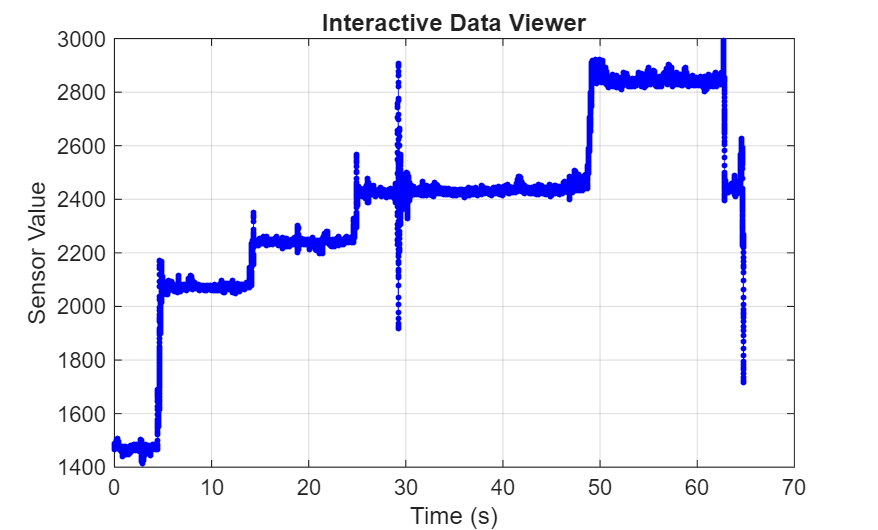

clear; clc; close all;

% โหลดข้อมูล
load('weight03.mat');

% ถ้ามี timeseries อยู่ในตัวแปร data
if isa(data, 'timeseries')
    t = data.Time;
    y = data.Data;
else
    error('ไม่พบ timeseries "data" ในไฟล์นี้');
end

% ถ้า y เป็น 3 มิติ ให้บีบเหลือ 1 มิติ
y = squeeze(y);

% ตรวจสอบความยาว
if length(t) ~= length(y)
    warning('ความยาว t และ y ไม่ตรงกัน กำลังปรับให้สั้นเท่ากัน...');
    n = min(length(t), length(y));
    t = t(1:n);
    y = y(1:n);
end

% วาดกราฟ
figure;
plot(t, y, 'b.-', 'MarkerSize', 8);
xlabel('Time (s)');
ylabel('Sensor Value');
title('Interactive Data Viewer');
grid on;
hold on;

% เปิดโหมด data cursor
dcm = datacursormode(gcf);
set(dcm, 'UpdateFcn', @myupdatefcn);
datacursormode on;


% ------------------------------
% ฟังก์ชันแสดงค่าที่คลิก
% ------------------------------
function txt = myupdatefcn(~, event_obj)
    pos = event_obj.Position;
    txt = {['Index: ', num2str(event_obj.DataIndex)], ...
           ['Time: ', num2str(pos(1))], ...
           ['Value: ', num2str(pos(2))]};
end